# Defining region of interest (ROI) and cropping data for local analysis

**Creation of ROI, extraction of data set, 1D concentration profile along ROI axis**

In order to analyze a specific section of the data set, the user can create a region of interest. To start with the creation of a ROI, a 3D reconstruction of the APT tip and a ranged pos file are required. The live scripts **FirstSteps **and **3D visualisation of APT data** will guide you through these required steps.

**Side note:** If a former 3D reconstruction was already saved, you can load the saved MATLAB figure and create a ROI. However, before starting with the first steps of creating the ROI, you have to open the figure, click on it, and enter *ax = gca; *in the comand line. After this, proceed with the following steps.

## Creating a ROI

In this toolbox three different shaped ROI are implemented. You can either create a box, a cylinder, or a sphere of defined dimensions.

### Creating a ROI box

The box shaped ROI is created by the *ROIcreateBox* function. The dimensions are defined by values corresponding to length, width, and height in x-, y-, and z-direction, respectively. The origin is determined by x, y, and z coordinates. You can also set the axis, in which the ROI is orientated.

All these inputs are optional. If no input is used, the default dimensions correspond to a cube with a side length of 10, an origin in (0,0,0) and the current axis of the figure.  

dimensions = [10 10 10]; % length, width, and height (x,y,z) of the ROI in nm
location = [0 0 0]; % origin coordinates of the ROI
roi_box = ROIcreateBox(dimensions,location,ax);
 

### Creating a ROI cylinder

To create a cylinder shaped ROI the *ROIcreateCylinder* function is used. All inputs are optional. The default values are a radius of 5 nm, a height of 10 nm, a origin of (0,0,0) and a number of segments, which depict the cylinder, of 32. Also, you can set the axis, in which the ROI is orientated.

This function needs the wanted radius, height, location, and number of segments of the cylinder.

radius = 5; % radius of the cylinder in nm
height = 10; % height of the cylinder in nm
location = [10 10 10]; % origin coordinates of the ROI
numSegments = 32; % number of segments of the cylinder
roi_cylinder = ROIcreateCylinder(radius,height,location,numSegments,ax);
 

### Creating a ROI sphere

The user can create a sphere shaped ROI with the *ROIcreateSphere* function. 

radius = 5; % radius of the sphere
subDivisions = 15; % number of subdivisions of the sphere
location = [10 10 10]; % origin coordinates of the ROI
roi_sphere = ROIcreateSphere(radius,subDivisions,location,ax);
 

## Manipulating the ROI

After the user created the ROI in the wanted shape it can be moved, turned and volumetrically changed with the *roiManipulate* app (see figure). 

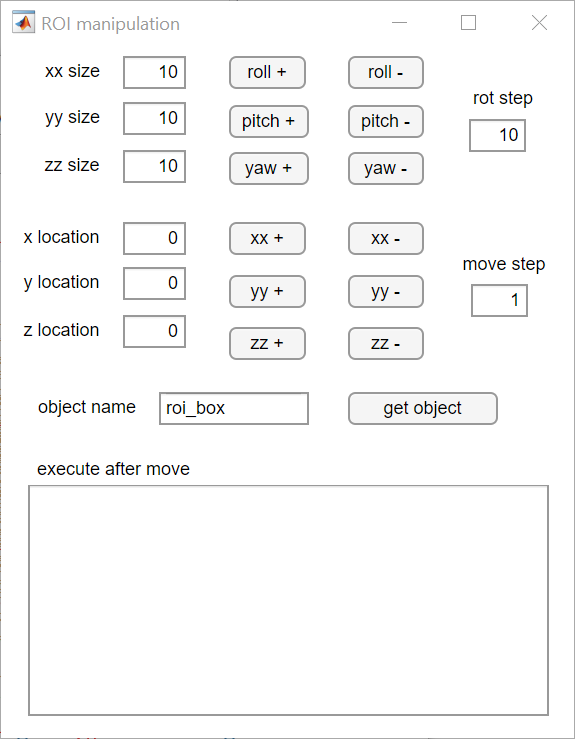

Before the user can change position and size of the ROI, the user has to give the app the object name and hit the *get object* button. Then the user can easily change the size of the ROI by entering it in the respective field. The location of the object can also be changed directly or via the buttons provided. With *rot step* or *move step*, the user can change the precision of the movement.

## Cropping the created ROI of the plotted data

With the function *posInConvexHull* it is possible to crop the data points encapsulated by the ROI and create a separated pos_roi file for further data analysis.  

roi = "roi_box"; % select the ROI
pos_roi = pos(posInConvexHull(pos,roi.Vertices),:);